%initialisation
u=0;
w=0;
c=0;
theta=0;


% A, B, C sont les matrices de l'espace d'état ici on veut représenter les
% oscillations d'un avion
C=[0 0 -1 0];
x=[u;w;c;theta];
A=[-0.0135 0.006 0 -9.81;0.0125 -0.727 350 0;0.009 -0.08 -0.745 0;0 0 1 0];
B=[0.77;-27.55;-20.7;0];
q=C.*x;

% Convertit la représentation d'état (state-space) en fonctions de transfert
% 0 indique que nous ne voulons pas inclure la matrice D dans la conversion
[de, q] = ss2tf(A, B, C, 0);

% Stocke le numérateur dans un vecteur
numerators = [de];

% Stocke le dénominateur dans un vecteur
denominator = [q];

% Crée un modèle de système de transfert à partir des numérateurs et dénominateurs
sys = tf(numerators, denominator);

% Trace le diagramme de Bode du système
bode(sys)

% Permet de superposer d'autres tracés sur le même graphique
hold on



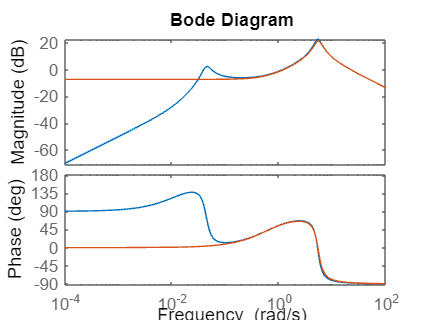

% Définition des coefficients du numérateur et du dénominateur
numerators = [12.73 * 1.62, 12.73];
denominator = [1, 1.76, 29.5];

% Création d'un modèle de fonction de transfert
B = tf(numerators, denominator); % fonction de transfert en boucle fermée (retour unitaire)

% Tracé du diagramme de Bode
bode(B)

% Désactive la superposition de graphiques sur le même axe
hold off


% Calcul des zéros et des pôles
zeros = 1 / 1.62;
x1 = (-1.76 - i * sqrt(114.9)) / 2;
x2 = (-1.76 + i * sqrt(114.9)) / 2;
poles = [x1, x2];

% Définition du gain
gain = 12.73;

% Création d'un modèle de système à pôles et zéros
% sys = zpk(zeros, poles, gain);


DETERMINATION DE KC

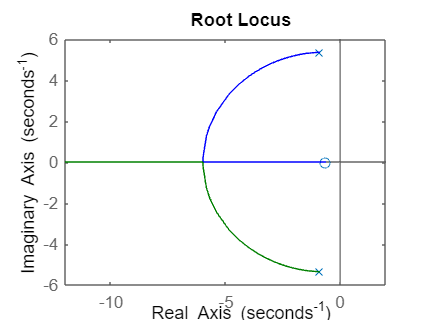

Kq=5.73;
Kg=0.175;
Kc=0.245;

rlocus(Kg*Kq*B)
hold off

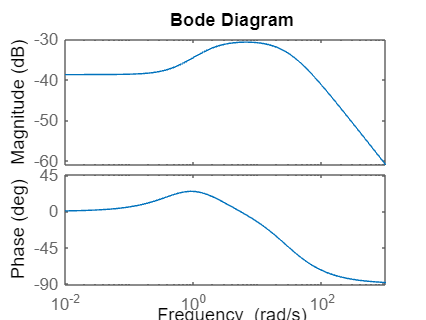

C=Kc*Kg*B/(1+Kq*Kc*B);
bode(C)

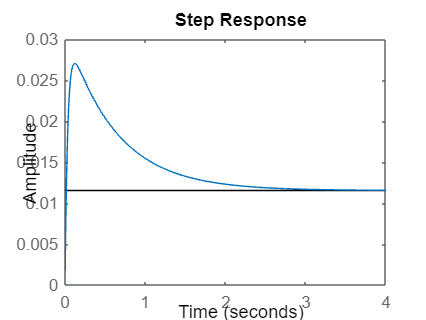

step(C)

l erreur est du à linfluence du zero et de la boucle de transfert

A2=[-1.76  1 ;-29.5 0];
B2=[20.62;12.73];
C2=[1 0];
%ltiview(A2,B2,C2)